# Predict Battery State of Charge Using Deep Learning

Source: MATLAB

Update: Neelanjana Pal

This example shows how to train a neural network to predict the state of charge of a battery by using deep learning.

Battery state of charge (SOC) is the level of charge of an electric battery relative to its capacity measured as a percentage. SOC is critical information for the vehicle energy management system and must be accurately estimated to ensure reliable and affordable electrified vehicles (xEV). However, due to the nonlinear temperature, health, and SOC dependent behavior of Li-ion batteries, SOC estimation is still a significant automotive engineering challenge. Traditional approaches to this problem, such as electrochemical models, usually require precise parameters and knowledge of the battery composition as well as its physical response. In contrast, using neural networks is a data-driven approach that requires minimal knowledge of the battery or its nonlinear behavior. [1]

This example is based on the MATLAB script from [1]. The example trains a neural network to predict the state of charge of a Li-ion battery, given time series data representing various features of the battery such as voltage, current, temperature, and average voltage and current (over the last 500 seconds). 

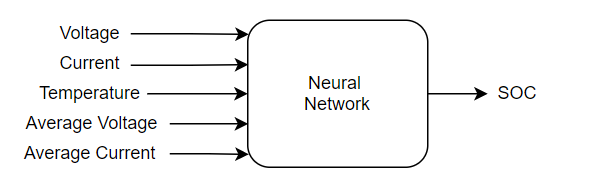

The training data contains a single sequence of experimental data collected while the battery powered an electric vehicle during a driving cycle with an external temperature of 25 degrees Celsius. The test data contains four sequences of experimental data collected during driving cycles at four different temperatures. This example uses the preprocessed data set `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` from [1]. For an example showing how use a trained neural network inside a Simulink® model to predict the SOC of a battery, see [Battery State of Charge Estimation in Simulink Using Deep Learning Network](docid:nnet_ug#mw_c53557b7-63bf-4221-9e67-a5919361e20f).

## Download Data

Each file in the `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` data set contains a time series `X` of five predictors (voltage, current, temperature, average voltage, and average current) and a time series `Y` of one target (SOC). Each file represents data collected at a different ambient temperature.

Specify the URL from where to download the data set. Alternatively, you can download this data set manually from [https://data.mendeley.com/datasets/cp3473x7xv/3](https://data.mendeley.com/datasets/cp3473x7xv/3). 

url = "https://data.mendeley.com/public-files/datasets/cp3473x7xv/files/ad7ac5c9-2b9e-458a-a91f-6f3da449bdfb/file_downloaded";

Set `downloadFolder` to where you want to download the ZIP file and the `outputFolder` to where you want to extract the ZIP file.

downloadFolder = tempdir;
outputFolder = fullfile(downloadFolder, "LGHG2@n10C_to_25degC");

Download and extract the `LG_HG2_Prepared_Dataset_McMasterUniversity_Jan_2020` data set.

if ~exist(outputFolder,"dir")
    fprintf("Downloading LGHG2@n10C_to_25degC.zip (56 MB) ... ")
    filename = fullfile(downloadFolder,"LGHG2@n10C_to_25degC.zip");
    websave(filename,url);
    unzip(filename,outputFolder)
end

## Prepare Training Data

For the training data, create a file datastore and specify the read function as the `load` function. The `load` function loads the data from the MAT file into a structure array.

folderTrain = fullfile(outputFolder,"Train");
fdsTrain = fileDatastore(folderTrain, ReadFcn=@load); 

Each file in this datastore contains both the predictors `X` and the targets `Y`.

Preview the  datastore. The output corresponds to a single sequence of targets `Y` from the first file.

preview(fdsTrain)

ans = struct with fields:
    X: [5×669956 double]
    Y: [0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 0.2064 … ]


PredictorTrain = readall(fdsTrain);
XT= PredictorTrain{1,1}.X

XT =     0.3851    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853
    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    

YT = PredictorTrain{1,1}.Y

YT =     0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064


## Prepare Test

For the testing data, create a file datastore and specify the read function as the `load` function. The `load` function loads the data from the MAT file into a structure array.

folderTest = fullfile(outputFolder,"Test");
fdsTest = fileDatastore(folderTest, ReadFcn=@load);

Each file in this datastore contains both the predictors `X` and the targets `Y`.

Preview the transformed datastore. The output corresponds to a single sequence of predictors `X` from the first file.

preview(fdsTest)

ans = struct with fields:
    X: [5×39293 double]
    Y: [1 1.0000 1.0000 1.0000 1.0000 1.0000 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9999 0.9998 0.9998 0.9998 0.9998 0.9998 0.9998 0.9997 0.9996 0.9994 0.9991 0.9989 0.9988 0.9987 0.9983 0.9982 0.9980 0.9980 0.9980 … ]


Specify the validation data as a subset of the testing data containing only the first file.

PredictorTest=readall(fdsTest) %Predictors test dataset -> used for validation while training

PredictorTest = 4×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


XT= PredictorTrain{1,1}.X

XT =     0.3851    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3852    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853    0.3853
    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    0.7510    

YT = PredictorTrain{1,1}.Y

YT =     0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064    0.2064


## Validation Data


V=1; % Selection of the Validation dataset, in this script the validation dataset is the same as Test dataset, but it can be changed 
X=PredictorTest{V,1}.X % X predictors Validation dataset 

X =     0.9673    0.9573    0.9537    0.9520    0.9511    0.9506    0.9503    0.9501    0.9498    0.9496    0.9495    0.9493    0.9492    0.9491    0.9490    0.9489    0.9488    0.9486    0.9485    0.9484    0.9484    0.9425    0.9028    0.8430    0.7942    0.7454    0.7088    0.7627    0.8262    0.7201    0.6984    0.7581    0.7938    0.8568    0.9244    0.9638    0.9764    0.9760    0.9793    0.9775    0.9716    0.9220    0.8830    0.8682    0.8395    0.7682    0.6984    0.6831    0.7546    0.8379
    0.7492    0.7470    0.7471    0.7471    0.7471    0.7470    0.7471    0.7470    0.7470    0.7470    0.7471    0.7471    0.7470    0.7471    0.7471    0.7471    0.7470    0.7471    0.7471    0.7471    0.7471    0.7410    0.7232    0.7025    0.6794    0.6553    0.6356    0.7187    0.7105    0.6022    0.6736    0.6838    0.7088    0.7514    0.7591    0.7635    0.7605    0.7602    0.7600    0.7580    0.7475    0.7345    0.7278    0.7229    0.7073    0.6416    0.6327    0.6308    0.7191    0

Y=PredictorTest{V,1}.Y

Y =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9996    0.9994    0.9991    0.9989    0.9988    0.9987    0.9983    0.9982    0.9980    0.9980    0.9980    0.9980    0.9981    0.9981    0.9981    0.9981    0.9981    0.9981    0.9980    0.9980    0.9979    0.9978    0.9975    0.9972    0.9970    0.9969


## Define Network Architecture

Define the network architecture. Set the number of inputs features to five (voltage, current, temperature, average voltage, and average temperature).

numFeatures = 5; 

Set the number of output features to one (SOC).

numResponses = 1;

Specify the number of hidden neurons.

numHiddenNeurons = 55; 

Define the layers of the network.

layers = [
    sequenceInputLayer(numFeatures,Normalization="zerocenter")
    fullyConnectedLayer(numHiddenNeurons)
    tanhLayer                            
    fullyConnectedLayer(numHiddenNeurons)
    leakyReluLayer(0.3)                  
    fullyConnectedLayer(numResponses)
    reluLayer
    regressionLayer];

Specify the training options. Train for 1200 epochs with mini-batches of size 1 using the "`adam`" solver. To prevent the gradients from exploding, set the gradient threshold to 1. Specify an initial learning rate of 0.01, a learning rate drop period of 400 and a learning rate drop factor of 0.1. Specify a validation frequency of 30. Experiments in Experiment Manager showed that the initial learning rate of 0.01 and the learning rate drop factor of 0.1 together minimize the validation error.

%Number of Epochs
Epochs  =  1200; 

%Number of epochs for dropping the learning rate
LearnRateDropPeriod = 400; 

%Initial Learning rate. Very important parameter
InitialLearnRate=0.01;

%Factor for dropping the learning rate, ex.: reduce to 10% of the current learning
% rate at every 'LearnRateDropPeriod
LearnRateDropFactor=0.1; 

%Validate the model at each Iterations when values is equal to 1.
validationFrequency = 30;

miniBatchSize = 1;
NET_Path = "Data folder"; 

options = trainingOptions('adam', ...                    % Adam optimizer
    'MaxEpochs',Epochs,'ExecutionEnvironment','cpu', ...% Select GPU if you works on computer with GPU
    'GradientThreshold',1, ...
    'InitialLearnRate',InitialLearnRate, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',LearnRateDropPeriod, ...
    'LearnRateDropFactor',LearnRateDropFactor, ...
    'L2Regularization',1, ...
    'ValidationData', {X,Y}, ...
    'Shuffle','never',...
    "Verbose",1,...
    'ValidationFrequency',validationFrequency, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress',...
    'CheckpointPath', NET_Path);

## Train Network

Train the network using `trainNetwork` with the specified training options.

%net = trainNetwork(XT,YT,layers,options);
load net.mat;

## Test Network

Make predictions on the test data using `predict`. To avoid having to pad the sequences to ensure that all sequences in a mini-batch have the same length, set the mini-batch size to 1.

XTs = readall(fdsTest)

XTs = 4×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


To remove the first 'N' and last 'NN' datapoints to compensate the lack of previous data, which wouldn't normally occur in a real life xEV application

N=50; 
NN=50;

Y_Pred_n10degC = predict(net,XTs{1, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_0degC = predict(net,XTs{2, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_10degC = predict(net,XTs{3, 1}.X,'MiniBatchSize',miniBatchSize);
Y_Pred_25degC = predict(net,XTs{4, 1}.X,'MiniBatchSize',miniBatchSize);

Y_Pred_n10degC(Y_Pred_n10degC>1) = 1;
Y_Pred_0degC(Y_Pred_0degC>1) = 1;
Y_Pred_10degC(Y_Pred_10degC>1) = 1;
Y_Pred_25degC(Y_Pred_25degC>1) = 1;

Plot the predicted and the target SOC for different ambient temperatures.

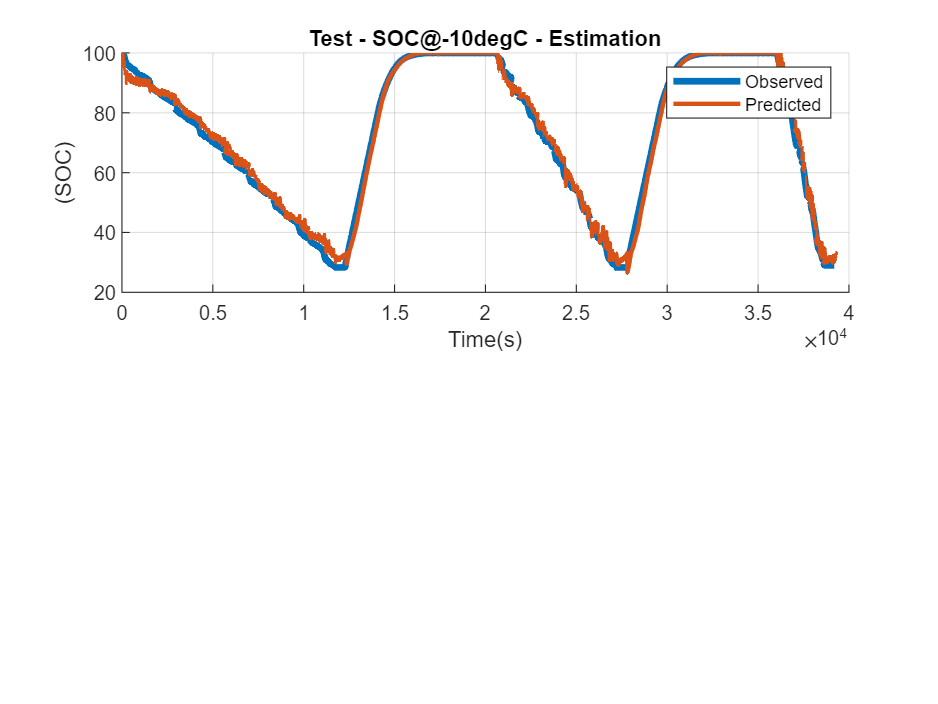

figure
subplot(2,1,1)
grid on
hold all;
plot(XTs{1, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_n10degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@-10degC - Estimation")
grid on

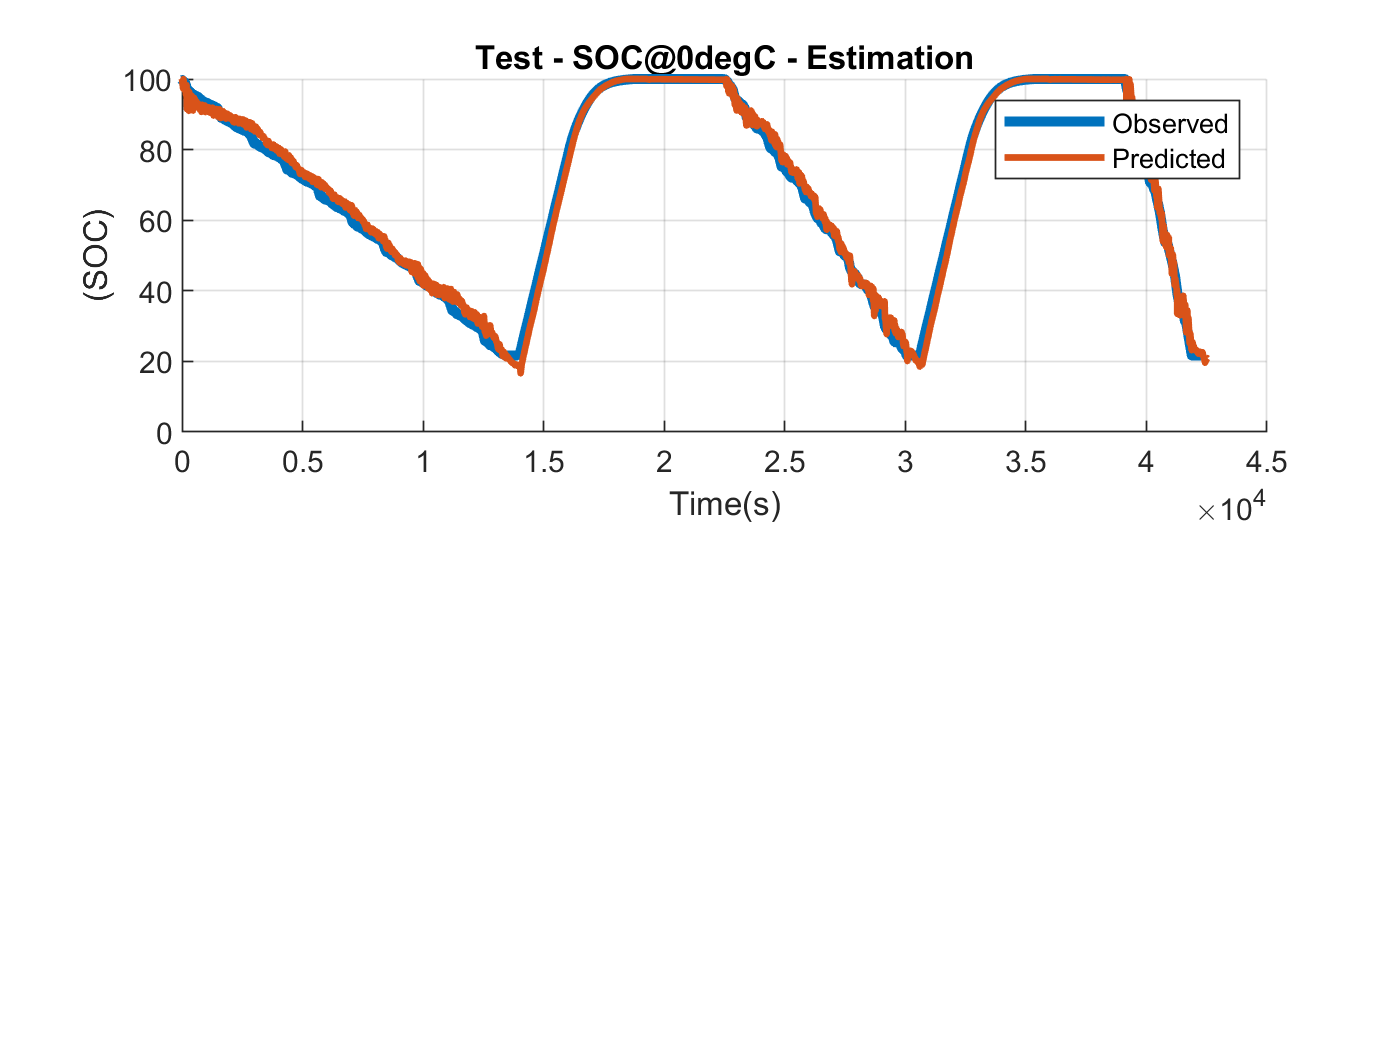


% subplot(2,1,2)
% grid on
% hold all;
% plot((Error_Test_n10degC)*100,'LineWidth',2,'LineStyle','-'); 
% legend("Error")
% ylabel("(%)")
% xlabel('Time(s)')
% title("Error") 
figure
subplot(2,1,1)
grid on
hold all;
plot(XTs{2, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_0degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@0degC - Estimation")
grid on

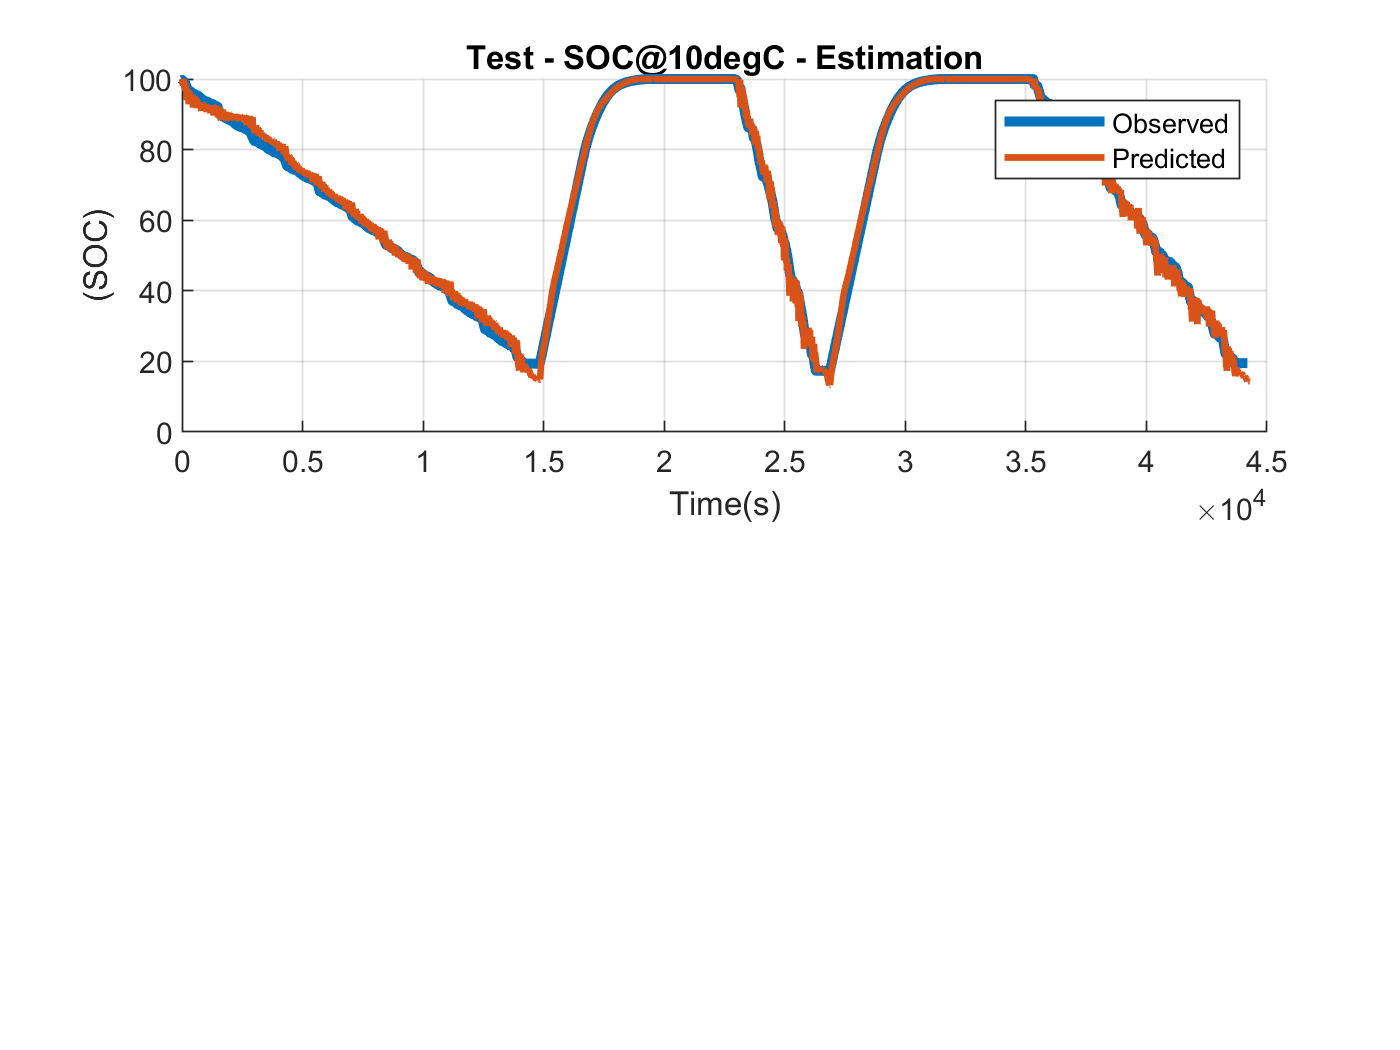


% subplot(2,1,2)
% grid on
% hold all;
% plot((Error_Test_0degC)*100,'LineWidth',2,'LineStyle','-'); 
% legend("Error")
% ylabel("(%)")
% xlabel('Time(s)')
% title("Error") 

figure
subplot(2,1,1)
grid on
hold all;
plot(XTs{3, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_10degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@10degC - Estimation")

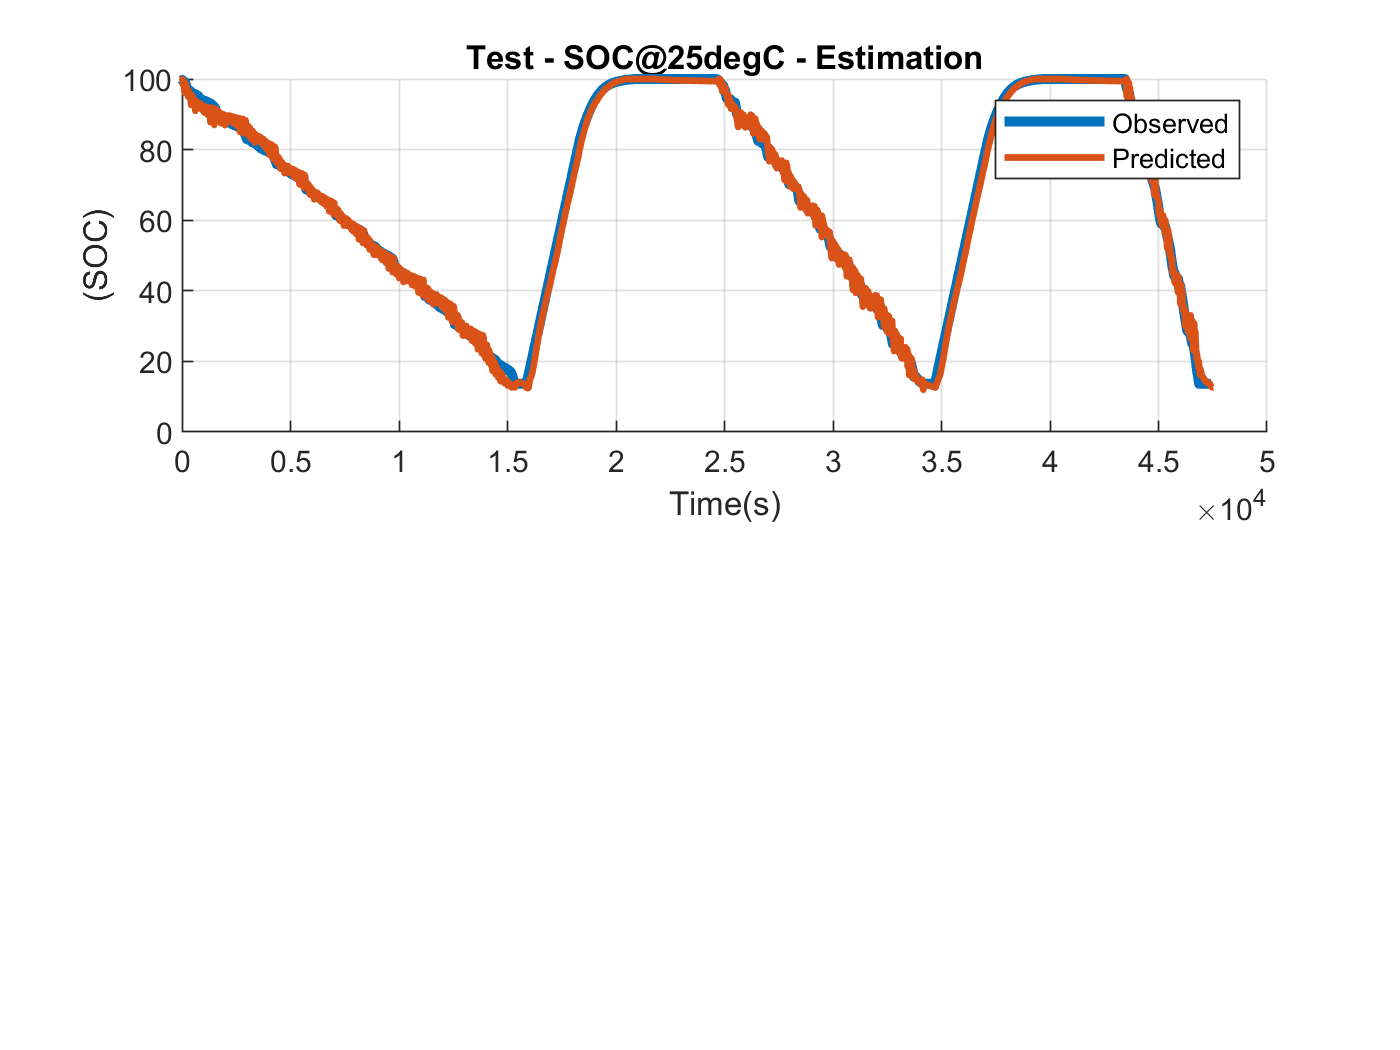

% grid on
% 
% subplot(2,1,2)
% grid on
% hold all;
% plot((Error_Test_10degC)*100,'LineWidth',2,'LineStyle','-'); 
% legend("Error")
% ylabel("(%)")
% xlabel('Time(s)')
% title("Error") 

figure
subplot(2,1,1)
grid on
hold all;
plot(XTs{4, 1}.Y(:,N:end-NN)*100,'LineWidth',3,'LineStyle','-'); 
plot(Y_Pred_25degC*100,'LineWidth',2,'LineStyle','-');

legend(["Observed" "Predicted"])
ylabel("(SOC)")
xlabel('Time(s)')
title("Test - SOC@25degC - Estimation")

% grid on
% 
% subplot(2,1,2)
% grid on
% hold all;
% plot((Error_Test_25degC)*100,'LineWidth',2,'LineStyle','-'); 
% legend("Error")
% ylabel("(%)")
% xlabel('Time(s)')
% title("Error")  

## References

[1] Kollmeyer, Phillip, Carlos Vidal, Mina Naguib, and Michael Skells. “LG 18650HG2 Li-Ion Battery Data and Example Deep Neural Network XEV SOC Estimator Script.” Mendeley, March 5, 2020. https://doi.org/10.17632/CP3473X7XV.3.

*Copyright 2021 The MathWorks, Inc.*